center1 = 7.5/10;
center2 = 7.5/10;
spread1 = 1/10;
spread2 = 1/10;

event1_density = @(p) double_stunted_gaussian(p,center1,spread1);
event2_density = @(p) double_stunted_gaussian(p,center2,spread2);
event1_gamma = @(p) double_stunted_gaussian_gamma(p,center1,spread1);
event2_gamma = @(p) double_stunted_gaussian_gamma(p,center2,spread2);

% Looking at Event 1 Only
moneyline_struct = moneyline_solver(event1_density,event1_gamma);
if moneyline_struct.matched_answers
    event1_profit = moneyline_struct.profit_numerical
else
    event1_profit_numerical = moneyline_struct.profit_numerical
    event1_profit_newton = moneyline_struct.profit_newton
end

event1_profit = 0.0614


% Looking at Event 2 Only
moneyline_struct = moneyline_solver(event2_density,event2_gamma);

if moneyline_struct.matched_answers
    event2_profit = moneyline_struct.profit_numerical
else
    event2_profit_numerical = moneyline_struct.profit_numerical
    event2_profit_newton = moneyline_struct.profit_newton
end

event2_profit_numerical = 0.0614

event2_profit_newton = 0

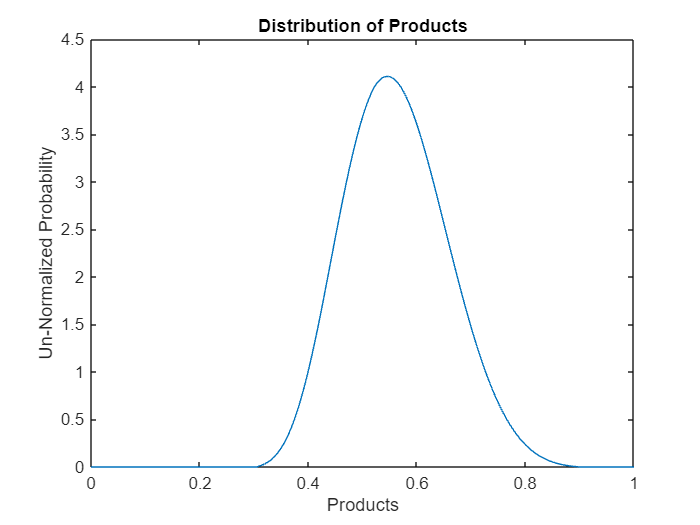


% Combine the Events

product_density = @(z) integral(@(p) event1_density(p).*event2_density(z./p)./p,0,1);
z_values = 0:.001:1;
product_values = zeros(1,length(z_values));
for index = 1:length(product_values)
    product_values(index) = product_density(z_values(index));
end

plot(z_values,product_values)
title('Distribution of Products')
xlabel('Products')
ylabel('Un-Normalized Probability')

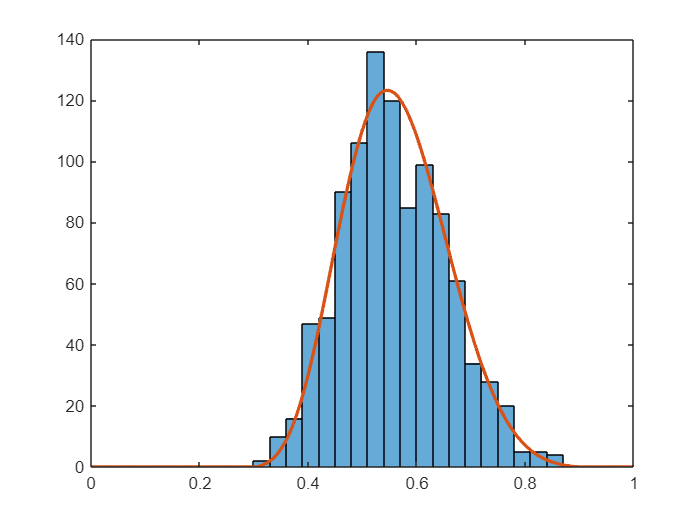


    % Use this distribution to generate 1e3 probability values and
    % numerically find the profitability of the moneyline

product_sample = nan(1,1e3);

for index = 1:1e3
    while isnan(product_sample(index))
        sample_value = rand();
        [~,z_index] = min(abs(z_values-sample_value));
        prob_of_use = product_values(z_index)/max(product_values);
        % I would love to contrast this method with the method that uses the 
        % inverse cdf with a random number input between [0 1] 

        r = rand();
        if r<=prob_of_use
            product_sample(index) = sample_value;
        end
    end
end
h = histogram(product_sample);
hold on
plot(z_values,product_values*1e6*(h.BinWidth)/sum(product_values),'LineWidth',2)
hold off


%% Product - 'Nuts and Bolts' numerical

product_spread = spread1*spread1*spread2*spread2 + spread1*spread1*center2*center2 + spread2*spread2*center1*center1

product_spread = 0.0114


num_samples = 1e3;
sample_probs = sort(product_sample);

sportsbook_profit_trad = 0;
palpha_final = nan;
pbeta_final = nan;

asymmetry_tolerance = 1; % In Basis Points of Total Money
% Would be interesting to plot max profitability as a function of asymmetry
% tolerance

f = waitbar(0,'Starting Process','Name','Solving For Traditional Sportsbook');
for palpha_index = 1:num_samples
    progress_value = (palpha_index^2+palpha_index)/(num_samples^2+num_samples);
    waitbar(progress_value,f,sprintf('%.1f Percent Complete',100*progress_value));
    for pbeta_index = 1:(palpha_index-1)
        palpha = sample_probs(palpha_index);
        pbeta = sample_probs(pbeta_index);
        alpha = 100*palpha/(1-palpha);
        beta = 100*pbeta/(1-pbeta);

        profit_favorite_win = length(1:pbeta_index) - 100/alpha*length(palpha_index:num_samples);
        profit_underdog_win = length(palpha_index:num_samples) - beta/100*length(1:pbeta_index);
        if abs(profit_favorite_win-profit_underdog_win) <= asymmetry_tolerance*num_samples/10000
            if max(profit_favorite_win,profit_underdog_win) > sportsbook_profit_trad
                sportsbook_profit_trad = max(profit_favorite_win,profit_underdog_win);
                palpha_final = palpha;
                pbeta_final = pbeta;
            end
        end

    end
end
close(f)
product_profit = sportsbook_profit_trad/num_samples

product_profit = 0.0597

#### OR (inclusive)

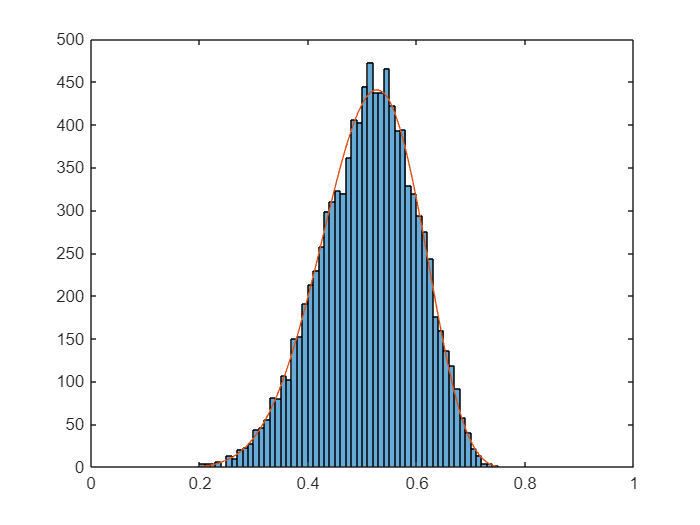

center1 = 3/10;
center2 = 3/10;
spread1 = 1/10;
spread2 = 1/10;

event1_density = @(p) double_stunted_gaussian(p,center1,spread1);
event2_density = @(p) double_stunted_gaussian(p,center2,spread2);
event1_gamma = @(p) double_stunted_gaussian_gamma(p,center1,spread1);
event2_gamma = @(p) double_stunted_gaussian_gamma(p,center2,spread2);
event1_inv_gamma = @(p) double_stunted_gaussian_inverse_gamma(p,center1,spread1);
event2_inv_gamma = @(p) double_stunted_gaussian_inverse_gamma(p,center2,spread2);

event1_values = event1_inv_gamma(rand(1,1e4));
event2_values = event2_inv_gamma(rand(1,1e4));

or_sample_values = nan(1,1e4);
for index = 1:1e4
    or_sample_values(index) = event1_values(index) + event2_values(index) - event1_values(index)*event2_values(index);
end
h = histogram(or_sample_values);
hold on

or_density = @(z) integral(@(p) event1_density(p).*event2_density((z-p)./(1-p))./(1-p),0,1);
z_values = 0:.001:1;
or_values = zeros(1,length(z_values));
for index = 1:length(or_values)
    or_values(index) = or_density(z_values(index));
end
A = 1e4/mean(or_values)*h.BinWidth;
plot(z_values,A*or_values,'LineWidth',2)